## Q1:

answers.q1 = 'The transition probabilty to any of these sites should be zero.';


## Q2:

P = xlsread('cancer_model.xls');
answers.q2 = P(:,2);
disp(answers.q2)

     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



## Q3:

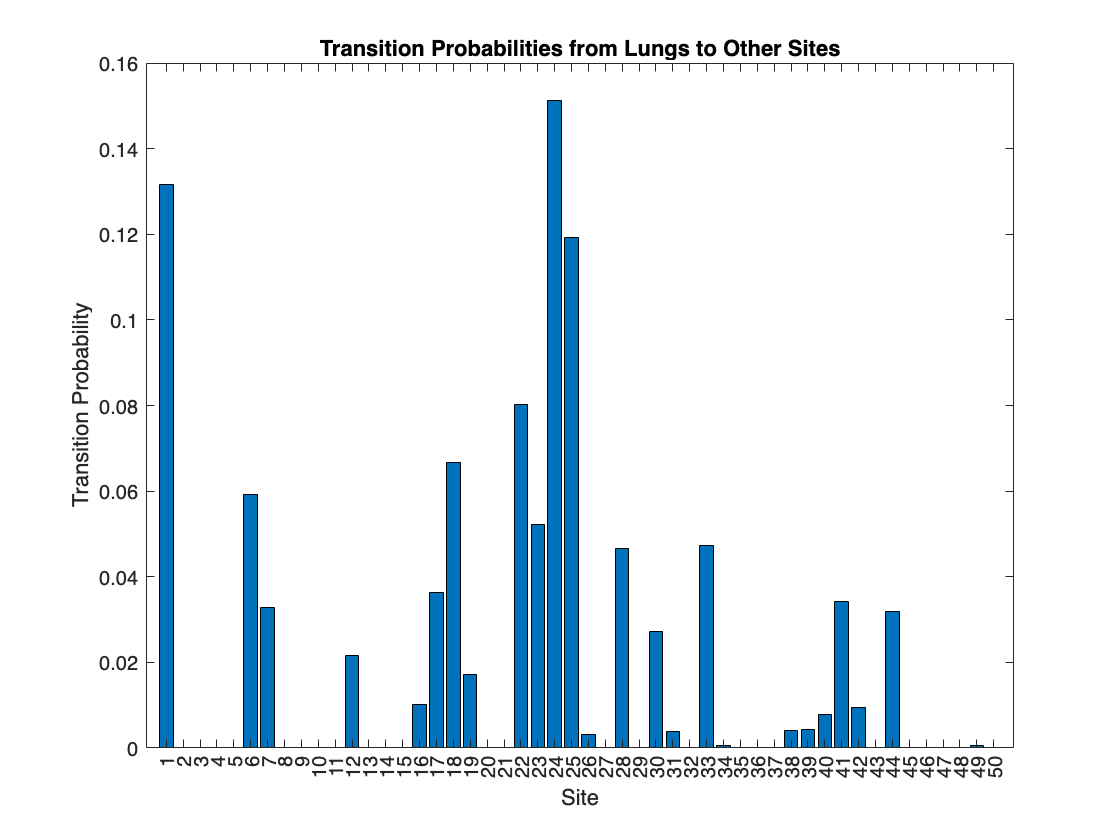

figure;
bar(P(23,:))
xlabel('Site')
xticks(1:50);
ylabel('Transition Probability')
title('Transition Probabilities from Lungs to Other Sites')

## Q4:

P100 = P^100;
ldist = P100(1,:);
answers.q4 = ldist;
disp(answers.q4)

    0.0953         0         0         0    0.0016    0.0614    0.0242         0         0         0         0    0.0194         0         0         0    0.0097    0.0275    0.0485    0.0145         0         0    0.0937    0.0775    0.1842    0.1228    0.0065         0    0.0372         0    0.0210    0.0194         0    0.0436    0.0016         0         0         0    0.0032    0.0129    0.0097    0.0291    0.0081         0    0.0242         0         0         0    0.0016    0.0016         0



## Q5:

chain = sim_MC(P, 23, 100);
counts = histc(chain, 1:50);
disp(counts)

     9     0     0     0     0     4     3     0     0     0     0     1     0     0     0     0     3     3     1     0     0    13     7    21    14     0     0     4     0     2     0     0     6     0     0     0     0     0     1     0     2     0     0     5     0     0     0     0     1     0



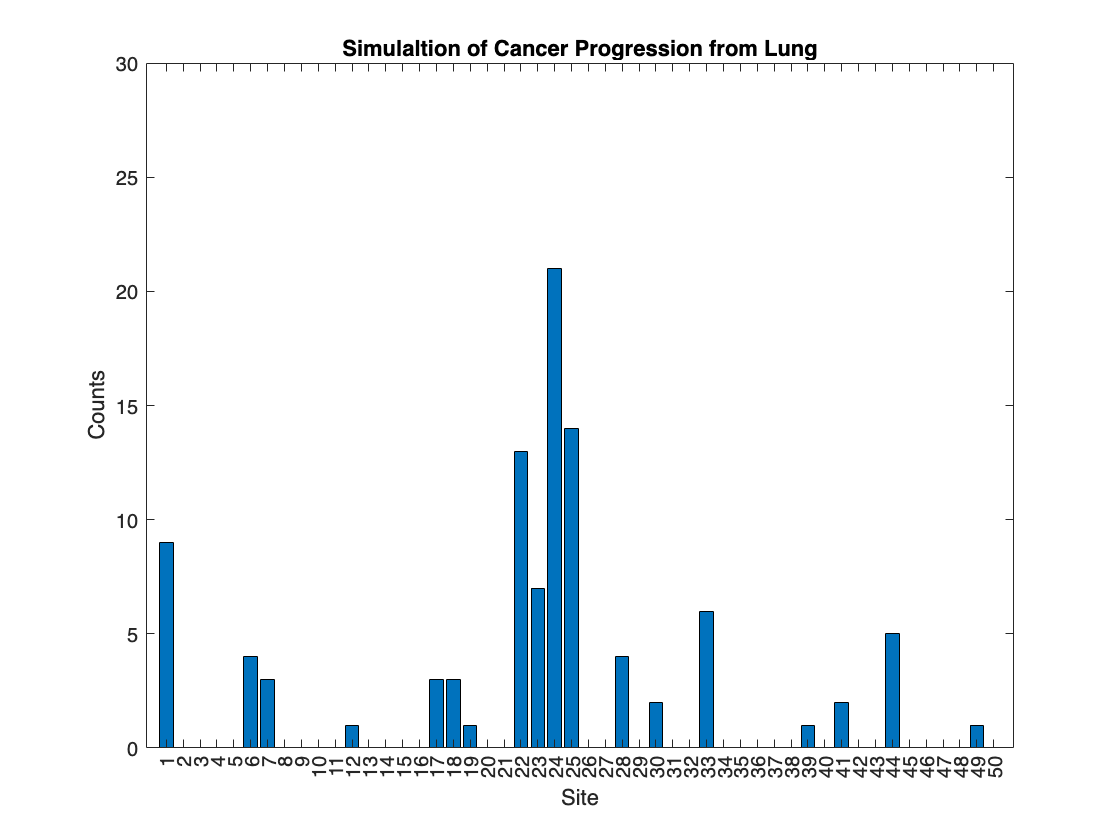

figure;
bar(counts)
xlabel('Site')
xticks(1:50);
ylabel('Counts')
ylim([0 30]);
title('Simulaltion of Cancer Progression from Lung')

## Q6:

fp_heart = NaN(1000, 1);
fp_pancreas = NaN(1000, 1);
fp_lymph = NaN(1000, 1);
for i = 1:1000
    chain = sim_MC(P, 23, 10000);
    fp_heart(i) = find(chain==17, 1)-1;
    fp_pancreas(i) = find(chain==28, 1)-1;
    fp_lymph(i) = find(chain==24, 1)-1;
end
answers.q6a = mean(fp_heart);
disp(answers.q6a)

   34.9910



answers.q6b = mean(fp_pancreas);
disp(answers.q6b)

   26.5490



answers.q6c = mean(fp_lymph);
disp(answers.q6c)

    5.8350



## Q7:

Q28 = P;
Q28(28,:) = 0;
Q28(:,28) = 0;
T28 = (eye(50)-Q28)\ones(50,1);

Q24 = P;
Q24(24,:) = 0;
Q24(:,24) = 0;
T24 = (eye(50)-Q24)\ones(50,1);

answers.q7 = [T28(23), T24(23)];
disp(answers.q7)

   26.6345    5.6165

